load('Reference.mat')

%Define parameters 
m1 = 1;
m2 = 0.05;
k1 = 1;
b1 = 0.001;
b2 = 0.02;
omSweep = linspace(0.7, 1.3, 50);
maxAmpBuilding = zeros(10,1);
k2s = linspace(0.04492, 0.04495, 10);

k2s =     0.0449    0.0449    0.0449    0.0449    0.0449    0.0449    0.0449    0.0449    0.0449    0.0449



for j=1:10
    k2 = k2s(j);
    %Numerically solve DE at each forcing frequency
    for i=1:length(omSweep)
    
        om = omSweep(i);
        
        %Copy code to solve DE here
        %Numerically solve DE
        x0 = [0;0;0;0];
        tvec = linspace(0,7000,35000);
        A = [0,0,1,0;0,0,0,1;-(k1+k2)/m1,k2/m1,-(b1+b2)/m1,b2/m1;k2/m2,-k2/m2,b2/m2,-b2/m2];
        [t,x] = ode45(@(t,x) A*x + [0;0;sin(om*t)/m1;0],tvec,x0);
    
        %Compute steady state solution and extract building oscillation amplitude 
        lt = length(t);
        per = 2*pi/om;
        [~,idx] = min(abs(t-(t(end)-5*per)));
        ampBuilding(i) = max(x(idx:lt,1));
    
    end
    maxAmpBuilding(j) = max(ampBuilding)
end

maxAmpBuilding =     8.5873
         0
         0
         0
         0
         0
         0
         0
         0
         0


maxAmpBuilding =     8.5873
    8.5873
         0
         0
         0
         0
         0
         0
         0
         0


maxAmpBuilding =     8.5873
    8.5873
    8.5873
         0
         0
         0
         0
         0
         0
         0


maxAmpBuilding =     8.5873
    8.5873
    8.5873
    8.5873
         0
         0
         0
         0
         0
         0


maxAmpBuilding =     8.5873
    8.5873
    8.5873
    8.5873
    8.5874
         0
         0
         0
         0
         0



[M, j] = min(maxAmpBuilding);
k2s(j);

%Plot
plot(k2s,maxAmpBuilding,'k');

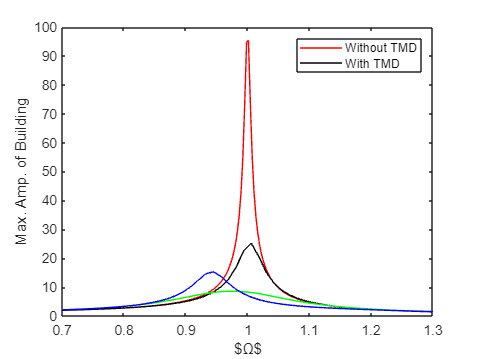

k2 = 0.02;
%Numerically solve DE at each forcing frequency
for i=1:length(omSweep)

    om = omSweep(i);
    
    %Copy code to solve DE here
    %Numerically solve DE
    x0 = [0;0;0;0];
    tvec = linspace(0,7000,35000);
    A = [0,0,1,0;0,0,0,1;-(k1+k2)/m1,k2/m1,-(b1+b2)/m1,b2/m1;k2/m2,-k2/m2,b2/m2,-b2/m2];
    [t,x] = ode45(@(t,x) A*x + [0;0;sin(om*t)/m1;0],tvec,x0);

    %Compute steady state solution and extract building oscillation amplitude 
    lt = length(t);
    per = 2*pi/om;
    [~,idx] = min(abs(t-(t(end)-5*per)));
    ampBuilding(i) = max(x(idx:lt,1));

end

%Plot
clf;
plot(OmRef,ampRef,'r'); hold on;
plot(omSweep,ampBuilding,'k'); hold on;

k2 = 0.045;
%Numerically solve DE at each forcing frequency
for i=1:length(omSweep)

    om = omSweep(i);
    
    %Copy code to solve DE here
    %Numerically solve DE
    x0 = [0;0;0;0];
    tvec = linspace(0,7000,35000);
    A = [0,0,1,0;0,0,0,1;-(k1+k2)/m1,k2/m1,-(b1+b2)/m1,b2/m1;k2/m2,-k2/m2,b2/m2,-b2/m2];
    [t,x] = ode45(@(t,x) A*x + [0;0;sin(om*t)/m1;0],tvec,x0);

    %Compute steady state solution and extract building oscillation amplitude 
    lt = length(t);
    per = 2*pi/om;
    [~,idx] = min(abs(t-(t(end)-5*per)));
    ampBuilding(i) = max(x(idx:lt,1));

end

plot(omSweep,ampBuilding,'g'); hold on;

k2 = 0.06;
%Numerically solve DE at each forcing frequency
for i=1:length(omSweep)

    om = omSweep(i);
    
    %Copy code to solve DE here
    %Numerically solve DE
    x0 = [0;0;0;0];
    tvec = linspace(0,7000,35000);
    A = [0,0,1,0;0,0,0,1;-(k1+k2)/m1,k2/m1,-(b1+b2)/m1,b2/m1;k2/m2,-k2/m2,b2/m2,-b2/m2];
    [t,x] = ode45(@(t,x) A*x + [0;0;sin(om*t)/m1;0],tvec,x0);

    %Compute steady state solution and extract building oscillation amplitude 
    lt = length(t);
    per = 2*pi/om;
    [~,idx] = min(abs(t-(t(end)-5*per)));
    ampBuilding(i) = max(x(idx:lt,1));

end

plot(omSweep,ampBuilding,'b'); hold off;
xlim([0.7,1.3]); ylabel('Max. Amp. of Building'); xlabel('$\Omega$');
legend('Without TMD','With TMD')

%Define parameters 
m1 = 1;
m2 = 0.05;
k1 = 1;
b1 = 0.001;
k2 = 0.045;
omSweep = linspace(0.7, 1.3, 50);
maxAmpBuilding = zeros(10,1);
b2s = linspace(0.0130, 0.0131, 10)

b2s =     0.0130    0.0131    0.0132    0.0133    0.0134    0.0136    0.0137    0.0138    0.0139    0.0140



for j=1:10
    b2 = b2s(j);
    %Numerically solve DE at each forcing frequency
    for i=1:length(omSweep)
    
        om = omSweep(i);
        
        %Copy code to solve DE here
        %Numerically solve DE
        x0 = [0;0;0;0];
        tvec = linspace(0,7000,35000);
        A = [0,0,1,0;0,0,0,1;-(k1+k2)/m1,k2/m1,-(b1+b2)/m1,b2/m1;k2/m2,-k2/m2,b2/m2,-b2/m2];
        [t,x] = ode45(@(t,x) A*x + [0;0;sin(om*t)/m1;0],tvec,x0);
    
        %Compute steady state solution and extract building oscillation amplitude 
        lt = length(t);
        per = 2*pi/om;
        [~,idx] = min(abs(t-(t(end)-5*per)));
        ampBuilding(i) = max(x(idx:lt,1));
    
    end
    maxAmpBuilding(j) = max(ampBuilding)
end

maxAmpBuilding =     6.4958
         0
         0
         0
         0
         0
         0
         0
         0
         0


maxAmpBuilding =     6.4958
    6.5005
         0
         0
         0
         0
         0
         0
         0
         0



[M, j] = min(maxAmpBuilding);
b2s(j)

%Plot
clf;
plot(b2s,maxAmpBuilding,'k');

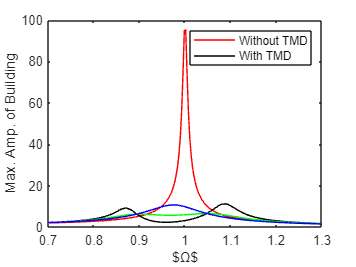

k2 = 0.045;

b2 = 0.005;
%Numerically solve DE at each forcing frequency
for i=1:length(omSweep)

    om = omSweep(i);
    
    %Copy code to solve DE here
    %Numerically solve DE
    x0 = [0;0;0;0];
    tvec = linspace(0,7000,35000);
    A = [0,0,1,0;0,0,0,1;-(k1+k2)/m1,k2/m1,-(b1+b2)/m1,b2/m1;k2/m2,-k2/m2,b2/m2,-b2/m2];
    [t,x] = ode45(@(t,x) A*x + [0;0;sin(om*t)/m1;0],tvec,x0);

    %Compute steady state solution and extract building oscillation amplitude 
    lt = length(t);
    per = 2*pi/om;
    [~,idx] = min(abs(t-(t(end)-5*per)));
    ampBuilding(i) = max(x(idx:lt,1));

end

%Plot
clf;
plot(OmRef,ampRef,'r'); hold on;
plot(omSweep,ampBuilding,'k'); hold on;

b2 = 0.013;
%Numerically solve DE at each forcing frequency
for i=1:length(omSweep)

    om = omSweep(i);
    
    %Copy code to solve DE here
    %Numerically solve DE
    x0 = [0;0;0;0];
    tvec = linspace(0,7000,35000);
    A = [0,0,1,0;0,0,0,1;-(k1+k2)/m1,k2/m1,-(b1+b2)/m1,b2/m1;k2/m2,-k2/m2,b2/m2,-b2/m2];
    [t,x] = ode45(@(t,x) A*x + [0;0;sin(om*t)/m1;0],tvec,x0);

    %Compute steady state solution and extract building oscillation amplitude 
    lt = length(t);
    per = 2*pi/om;
    [~,idx] = min(abs(t-(t(end)-5*per)));
    ampBuilding(i) = max(x(idx:lt,1));

end

plot(omSweep,ampBuilding,'g'); hold on;

b2 = 0.025;
%Numerically solve DE at each forcing frequency
for i=1:length(omSweep)

    om = omSweep(i);
    
    %Copy code to solve DE here
    %Numerically solve DE
    x0 = [0;0;0;0];
    tvec = linspace(0,7000,35000);
    A = [0,0,1,0;0,0,0,1;-(k1+k2)/m1,k2/m1,-(b1+b2)/m1,b2/m1;k2/m2,-k2/m2,b2/m2,-b2/m2];
    [t,x] = ode45(@(t,x) A*x + [0;0;sin(om*t)/m1;0],tvec,x0);

    %Compute steady state solution and extract building oscillation amplitude 
    lt = length(t);
    per = 2*pi/om;
    [~,idx] = min(abs(t-(t(end)-5*per)));
    ampBuilding(i) = max(x(idx:lt,1));

end

plot(omSweep,ampBuilding,'b'); hold off;
xlim([0.7,1.3]); ylabel('Max. Amp. of Building'); xlabel('$\Omega$');
legend('Without TMD','With TMD')